# LAB1 MATLAB Programming

Name(SID) and Name(SID)

## Introduction

MATLAB is a powerful tool to ......

## Results and Analysis

### 4.2

#### (a)

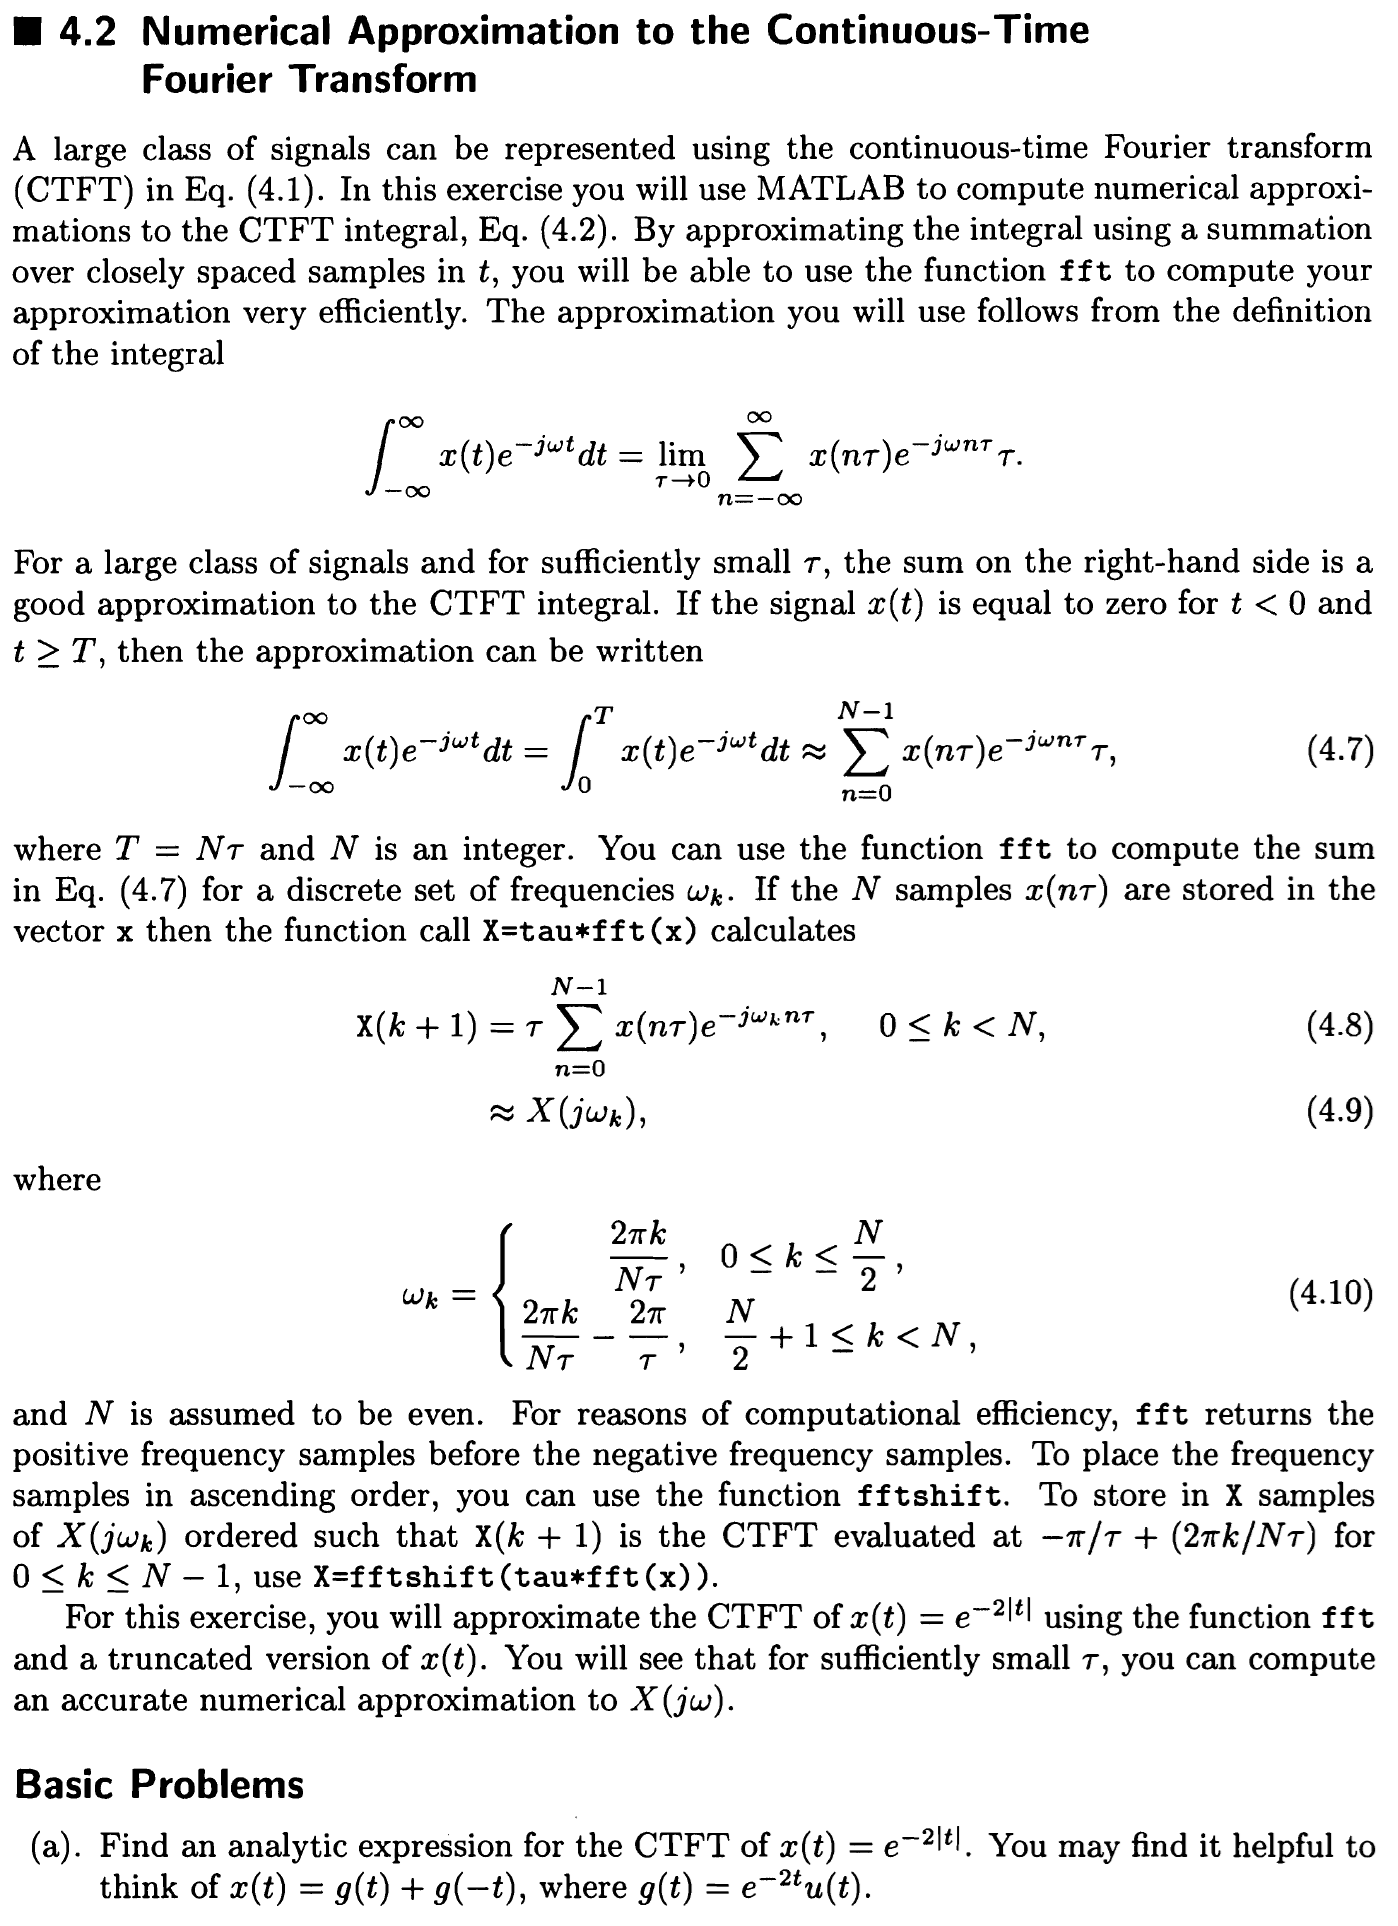

Initialize.

clear; clc; close all;

Calculate the analytic expression for $x(t)$.


$$\begin{array}{rcl}
G(j\omega) & = & F\{g(t)\} \\
& = & \frac{1}{2+j\omega}
\end{array}$$



$$\begin{array}{rcl}
X(j\omega) & = & F\{x(t)\} \\
& = & F\{g(t)+g(-t)\} \\
& = & F\{g(t)\}+F\{g(-t)\} \\
& = & G(j\omega)+G(-j\omega) \\
& = & \frac{1}{2+j\omega}+\frac{1}{2-j\omega}
\end{array}$$


#### (b)

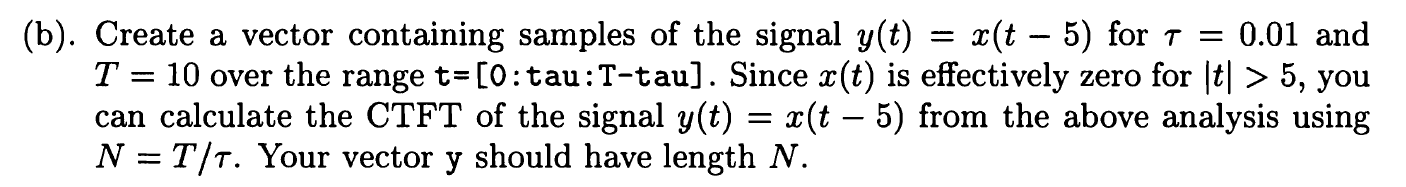

Create $\tau$, $T$, $N$, vector $t_x$, $x$, $t$, $y$.

tau = 0.01;
T = 10;
N = T/tau;
t = 0:tau:T-tau;
tx = t-5;
x = exp(-2*abs(tx));
y = x;

#### (c)

Calculate CTFT of $y(t)=x(t-5)$.

Y = fftshift(tau*fft(y));

#### (d)

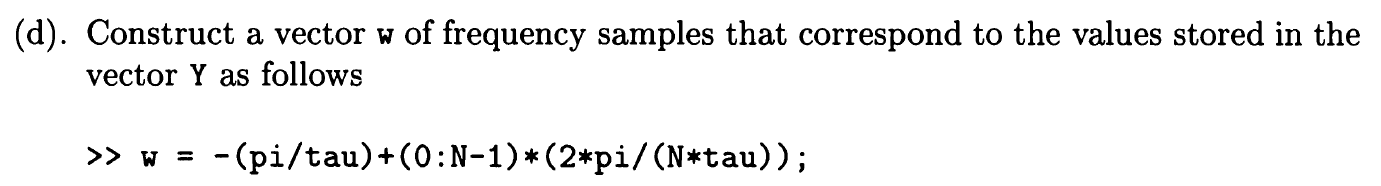

w = -(pi/tau)+(0:N-1)*(2*pi/(N*tau));

#### (e)

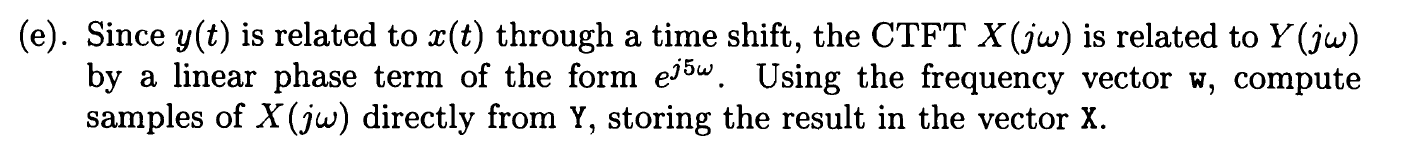

X = Y.*exp(1i*5*w);

#### (f)

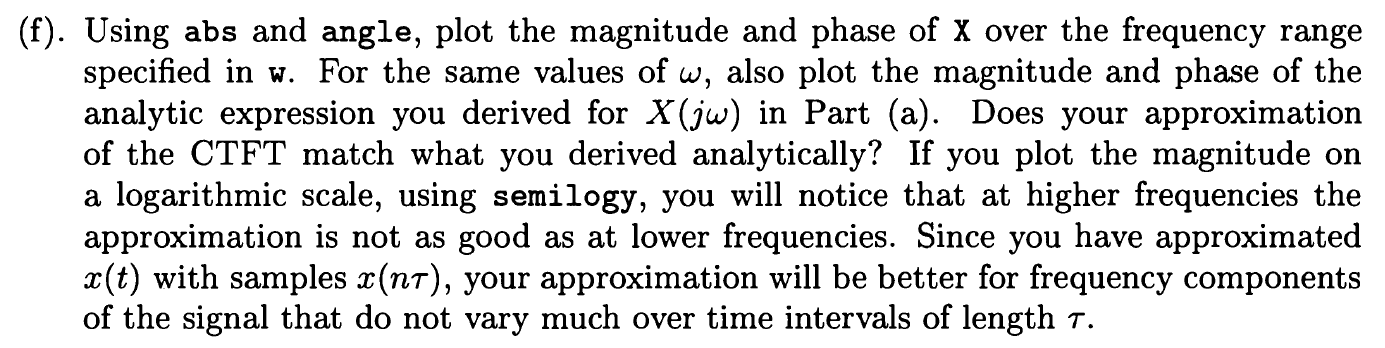

Calculate $X_{abs}$, $X_{angle}$.

Xabs = abs(X);
Xangle = angle(X);

Calculate $X_a$, $X_{abs_a}$, $X_{angle_a}$.

X_a = 1./(2+1i*w)+1./(2-1i*w);
Xabs_a = abs(X_a);
Xangle_a = angle(X_a);

Plot $X_{abs}$, $X_{abs_a}$, $X_{angle}$, $X_{angle_a}$.

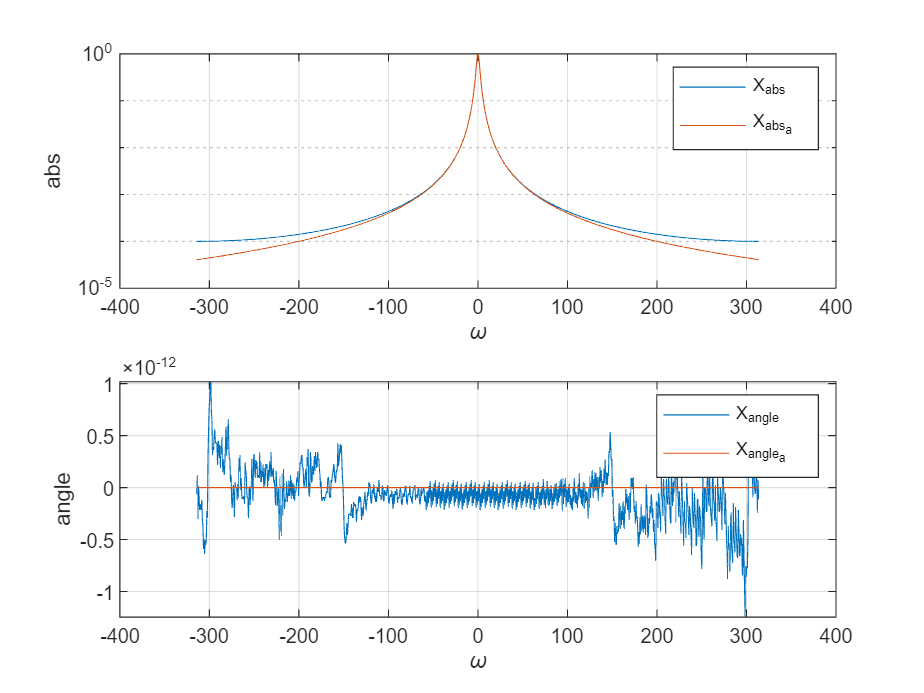

figure;
subplot(2,1,1);
semilogy(w,Xabs,w,Xabs_a);
legend("X_{abs}","X_{abs_a}");
grid on;
xlabel("\omega");
ylabel("abs");
subplot(2,1,2);
plot(w,Xangle,w,Xangle_a);
legend("X_{angle}","X_{angle_a}");
grid on;
xlabel("\omega");
ylabel("angle");

The approximation is totally matches when the frequency is low. But when the frequency is high, the approximation is not such accurate.

#### (g)

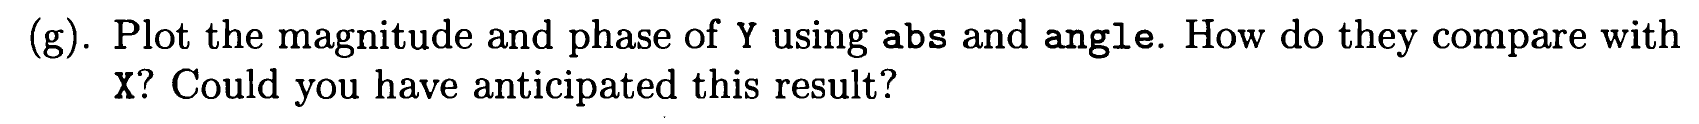

Calculate $Y_{abs}$, $Y_{angle}$.

Yabs = abs(Y);
Yangle = angle(Y);

Plot $X_{abs}$, $Y_{abs}$, $X_{angle}$, $Y_{angle}$.

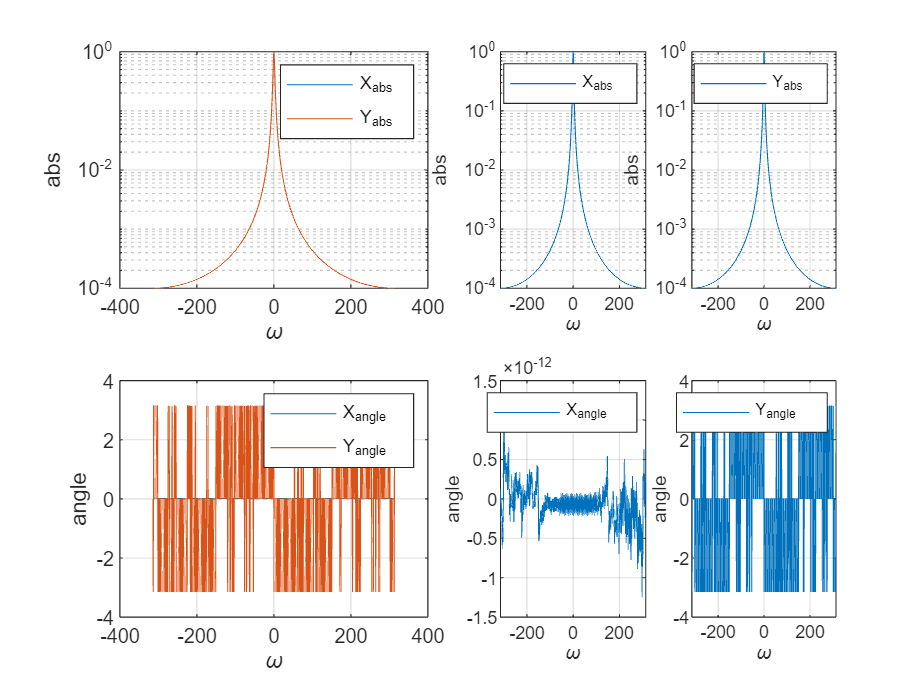

figure;
subplot(2,2,1);
semilogy(w,Xabs,w,Yabs);
legend("X_{abs}","Y_{abs}");
grid on;
xlabel("\omega");
ylabel("abs");
subplot(2,2,3);
plot(w,Xangle,w,Yangle);
legend("X_{angle}","Y_{angle}");
grid on;
xlabel("\omega");
ylabel("angle");
subplot(2,4,3);
semilogy(w,Xabs);
legend("X_{abs}");
grid on;
xlabel("\omega");
ylabel("abs");
subplot(2,4,4);
semilogy(w,Yabs);
legend("Y_{abs}");
grid on;
xlabel("\omega");
ylabel("abs");
subplot(2,4,7);
plot(w,Xangle);
legend("X_{angle}");
grid on;
xlabel("\omega");
ylabel("angle");
subplot(2,4,8);
plot(w,Yangle);
legend("Y_{angle}");
grid on;
xlabel("\omega");
ylabel("angle");

$X_{abs}$ and $Y_{abs}$ are the same while $X_{angle}$ and $Y_{angle}$ are very different. It's because the time shift only leads to phase shift in frequency domain, which is also mentioned in **(e)**.

### 4.6

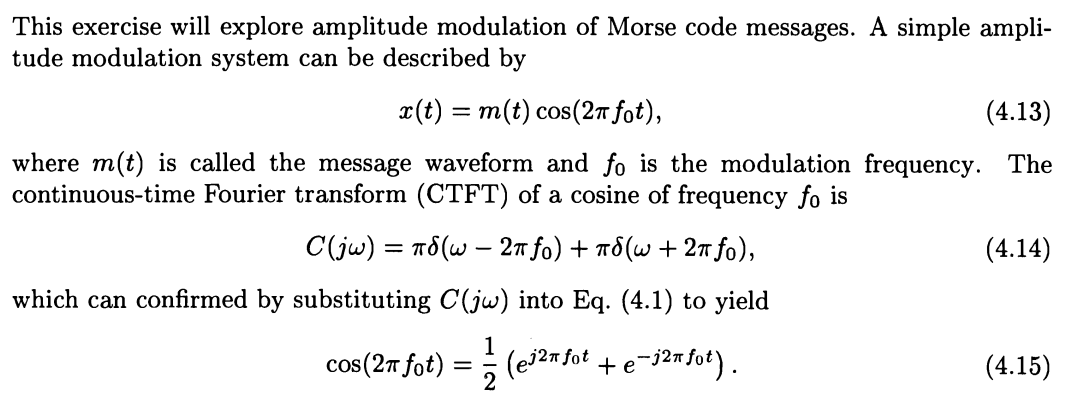

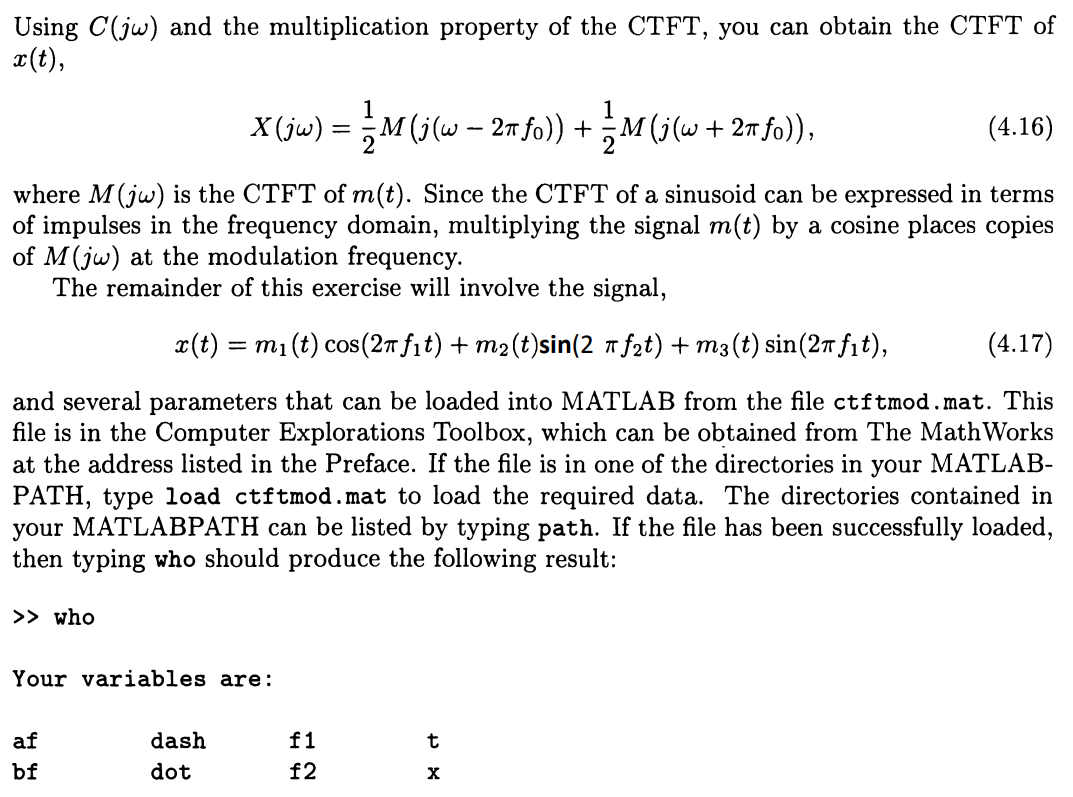

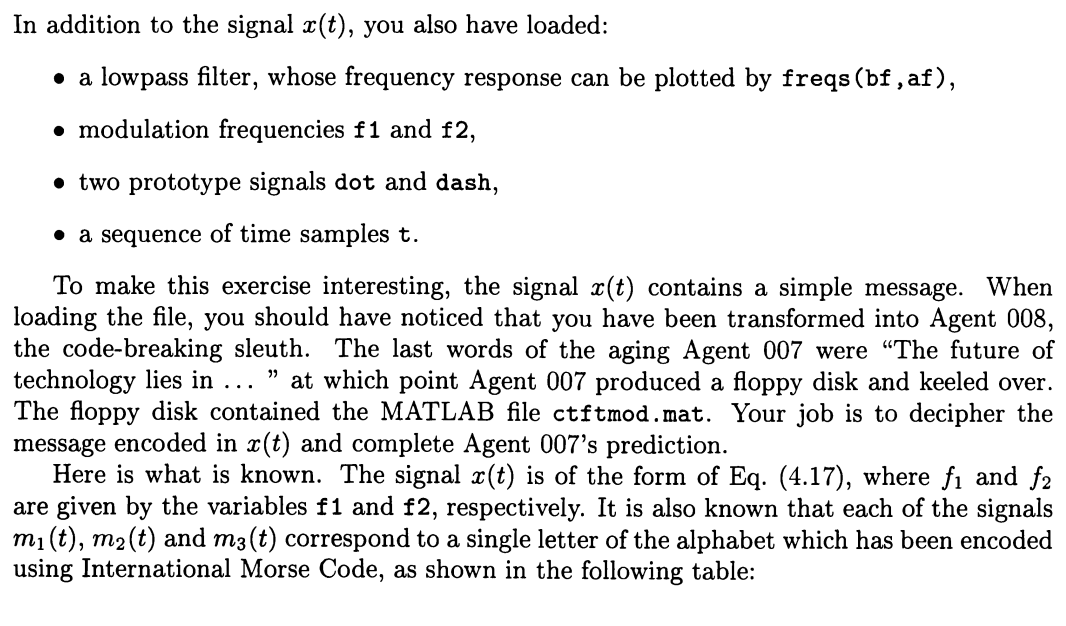

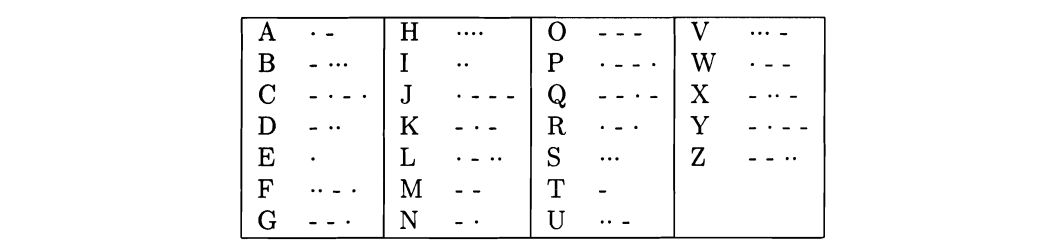

clc;clear;close all;

Load the file *ctftmod.mat*.

load lab4\ctftmod.mat

#### (a)

#### 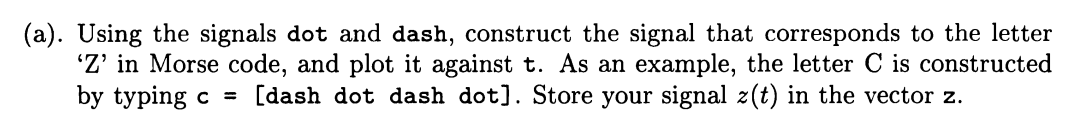

Create the signal of $Z$ in Morse code, plot it against $t$, and store the signal in the vector $z$.

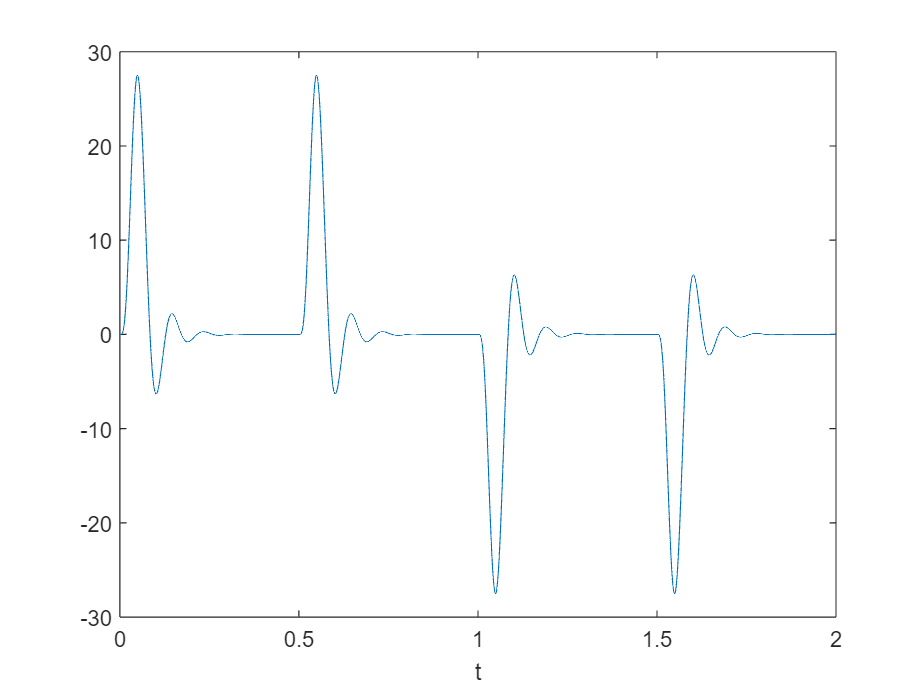

z = [dash dash dot dot];
figure;
plot(t,z);xlabel("t");

#### (b)

Plot the frequency response of the lowpass filter.

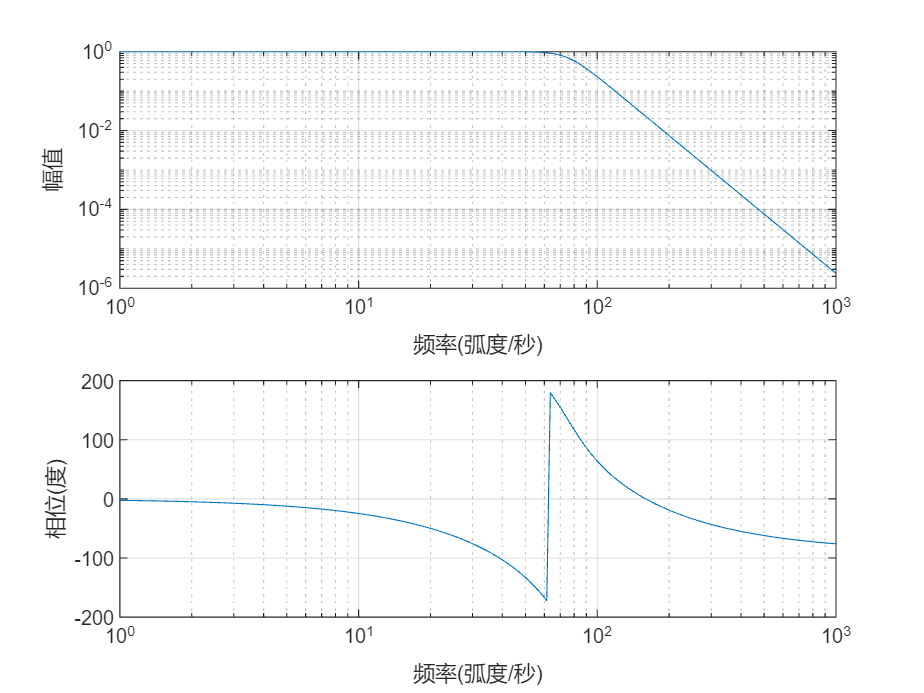

freqs(bf,af);

#### (c)

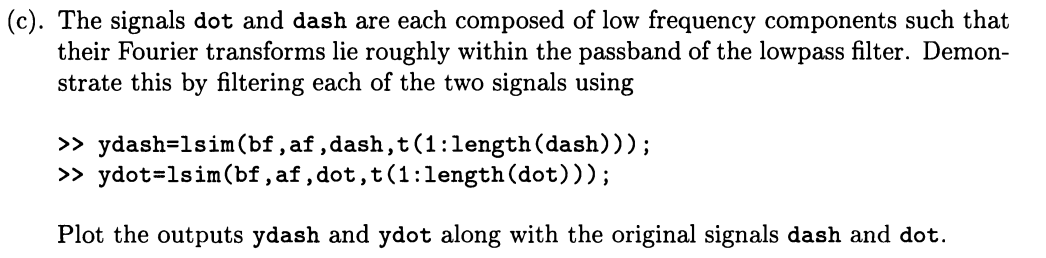

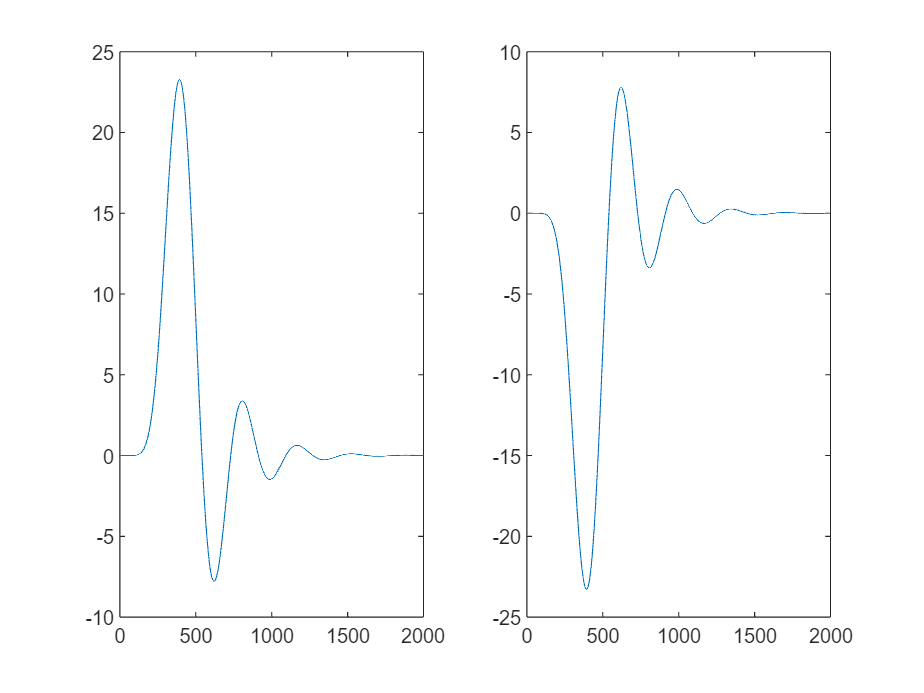

ydash = lsim(bf,af,dash,t(1:length(dash)));
ydot = lsim(bf,af,dot,t(1:length(dot)));
figure;
subplot(1,2,1);
plot(ydash);
subplot(1,2,2);
plot(ydot);

#### (d)

#### (e)

#### (f)

#### (g)

### Functions

## Expeience

........................